clear;
clc;

# Plant

#### States Description

- x0 state: Motor velocity in rpm.

- x1 state: Motor Position in deg.

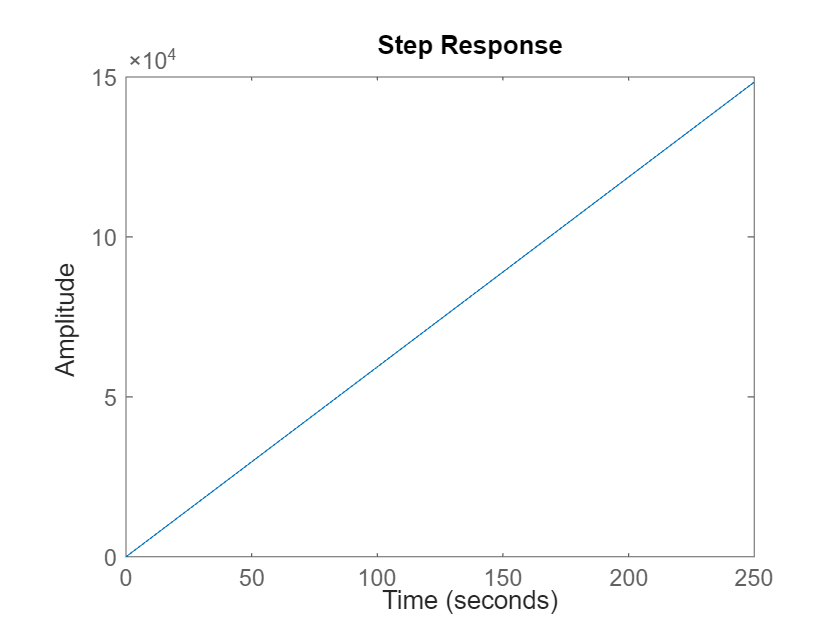

A = [-33.95 0; 360 0];
B = [55.99; 0];
C = [0 1];
D = 0;
plant_c = ss(A,B,C,D);
step(plant_c);

% Controlability verification
rank(ctrb(plant_c.A,plant_c.B))

ans = 2

## Discretization

Ts = 0.005;
plant_d = c2d(plant_c,Ts,'zoh');
% Plant poles
pole(plant_d)

ans =     1.0000
    0.8439


## Internal Model (**Two Integrators using forward approximation**)

% Internal Model Matrices
A_int_d = [1 Ts; 0 1];
B_int_d = [0; Ts];
% Augmented System
A_aug_d = [plant_d.A zeros(2,2); -B_int_d*plant_d.C A_int_d];
B_aug_d = [plant_d.B; zeros(2,1)];
C_aug_d = [plant_d.C, zeros(1,2)];
D_aug_d = 0;
aug_plant_d = ss(A_aug_d, B_aug_d, C_aug_d, D_aug_d, Ts);

# Control Design

#### Parameters

Overshoot [Mp] <= 25%, Velocity Error [Ev] = 0

The Controller is design for 50 deg movements. 

## 1. Pole Placement + IMP 

#### Pole selection

% Plant states poles (Dominant poles)
s1 = -4+0.8j;
s2 = -4-0.8j;
% Internal Model Poles
s3 = -40;
s4 = -45;
% Pole convertion to discrete using e^(Ts*s)
p = [exp(Ts*s1), exp(Ts*s2), exp(Ts*s3), exp(Ts*s4)]

p =    0.9802 + 0.0039i   0.9802 - 0.0039i   0.8187 + 0.0000i   0.7985 + 0.0000i


#### K calculation

K_pp = place(A_aug_d,B_aug_d,p);
A_cl_pp = A_aug_d-B_aug_d*K_pp;
B_cl_pp = [zeros(2,1); B_int_d];
sys_cl_pp = ss(A_cl_pp,B_cl_pp,C_aug_d,0,Ts);
pole(sys_cl_pp)

ans =    0.7985 + 0.0000i
   0.8187 + 0.0000i
   0.9802 + 0.0039i
   0.9802 - 0.0039i


#### Step Response

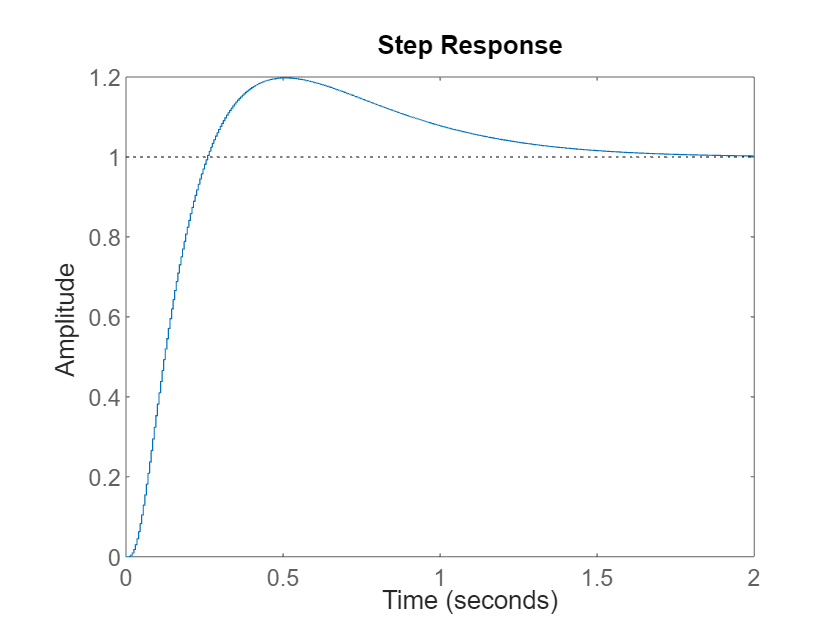

step(sys_cl_pp);

#### Ramp Response

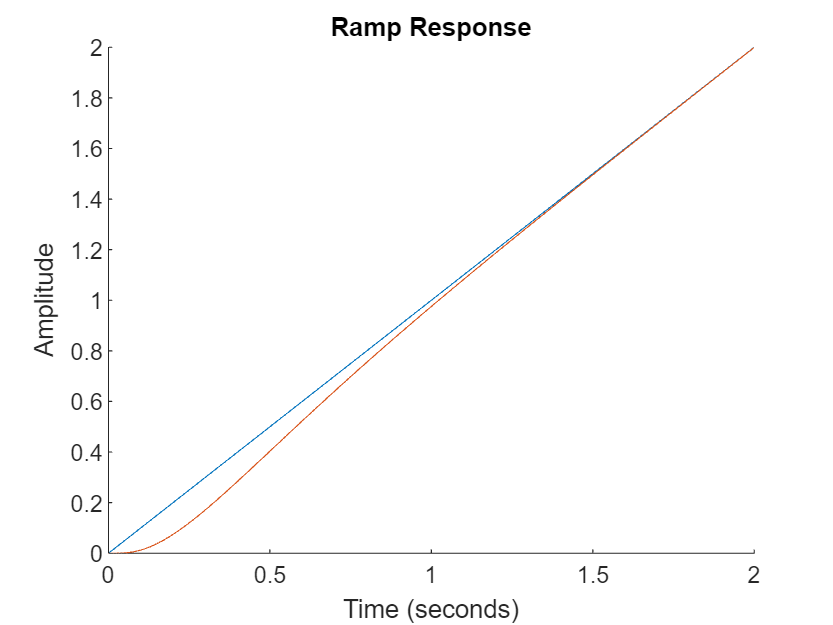

figure;
hold on;
t=0:0.005:2;
title('Ramp Response');
xlabel('Time (seconds)');
ylabel('Amplitude');
[y,t]=lsim(sys_cl_pp,t,t);
plot(t,t);
plot(t,y);

#### Final Matrices

A=plant_d.A;
B=plant_d.B;
C=plant_d.C;
A_im = A_int_d;
B_im = B_int_d;
K_x_pp = K_pp(1:2);
K_im_pp = K_pp(3:4);

## 2. Pole Placement + IMP + Ludenberg estimator 

## *3. LQR + IMP*

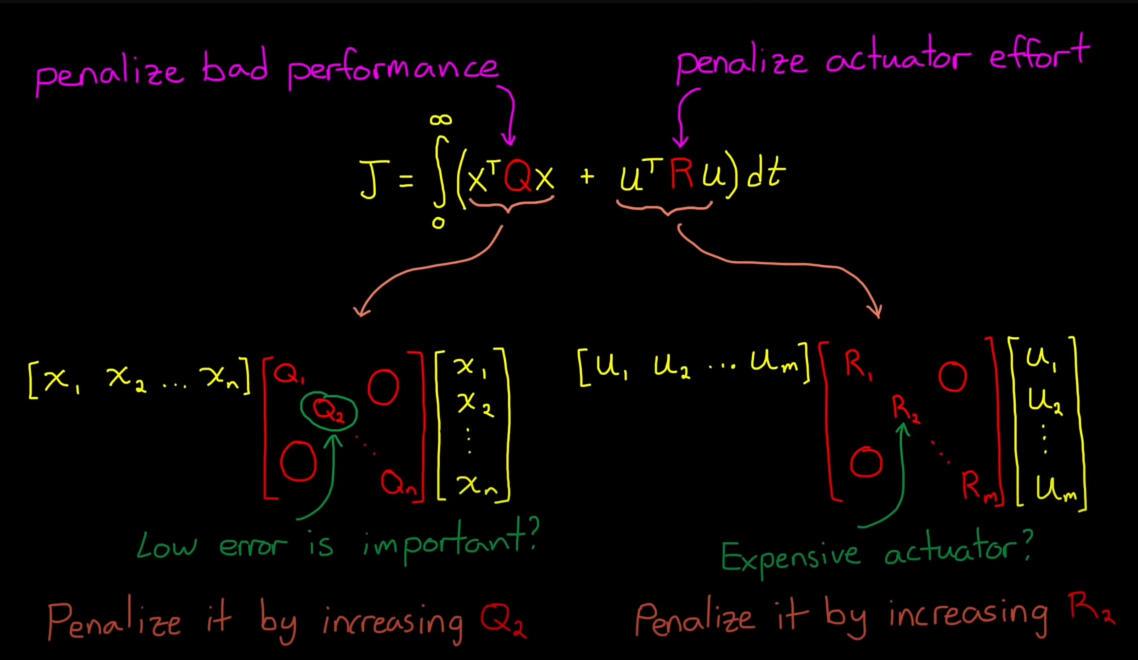

#### *Matrix Selection*

                     % Posible Effects (Conjectures)
Q = [20 0 0 0; ...   % Reward Velocity p<erformance.
     0 0.35 0 0; ... % Reward Position performance but due to the fact that Internal model is present, the error here is zero. (Lowering makes the controller faster but increses overshoot)
     0 0 70 0; ...   % Reward stationary error performance. (Lowers stabilization time)
     0 0 0 2];       % Reward stationary speed error performance.
R = 5;               % Penalize actuator effort so reduces the risk of saturation.
Q=Q*0.2;


                     
%Q = [20 0 0 0; ...
%     0 0.35 0 0; ...
%     0 0 70 0; ...
%     0 0 0 2];
% Q=Q*0.3;
%R = 5;

#### K calculation

K_lq = dlqr(A_aug_d,B_aug_d,Q,1)

K_lq =     1.7314    0.2326   -2.7295   -1.2244


A_cl_lq = A_aug_d-B_aug_d*K_lq;
B_cl_lq = [zeros(2,1); B_int_d];
sys_cl_lq = ss(A_cl_lq,B_cl_lq,C_aug_d,0,Ts);
pole(sys_cl_lq)

ans =    0.5961 + 0.0000i
   0.7756 + 0.0000i
   0.9855 + 0.0117i
   0.9855 - 0.0117i


#### Step Response

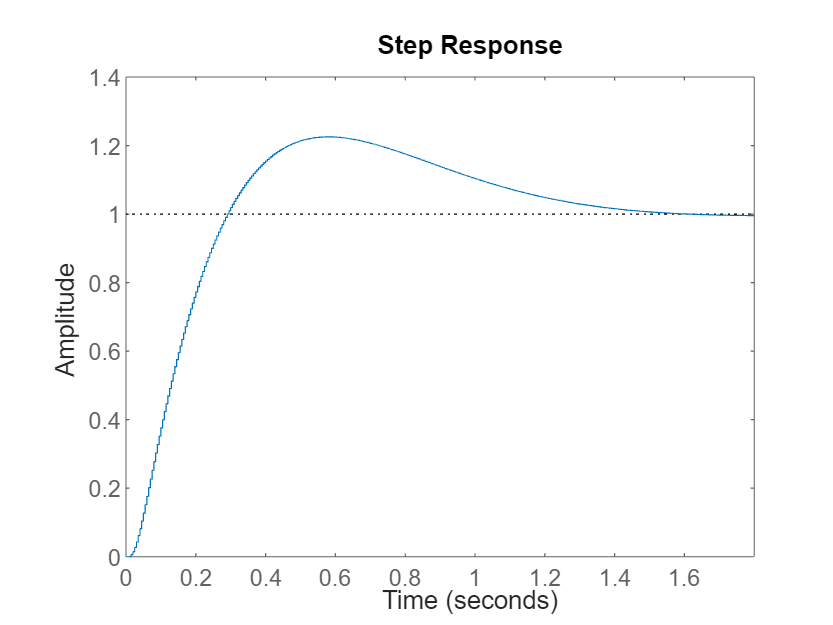

figure;
step(sys_cl_lq);

#### Ramp Response

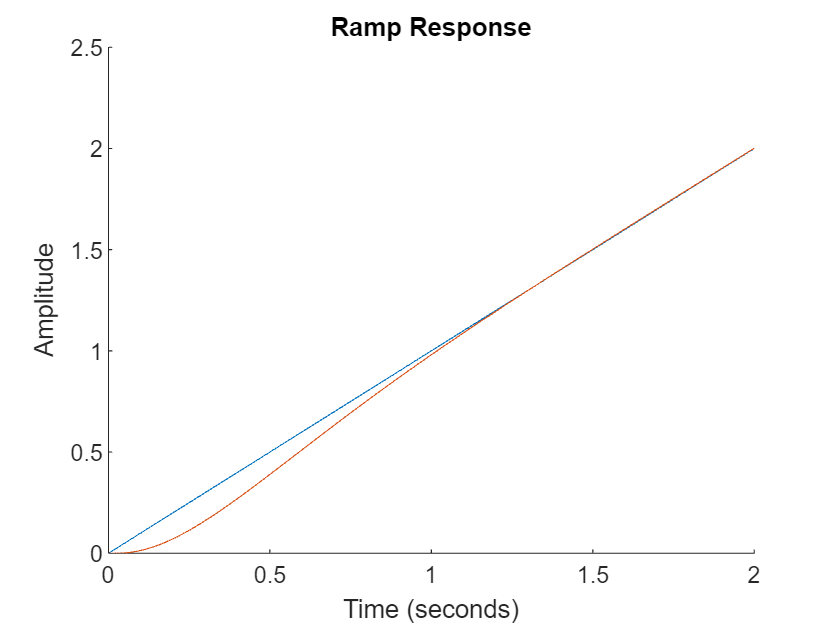

figure;
hold on;
t=0:0.005:2;
title('Ramp Response');
xlabel('Time (seconds)');
ylabel('Amplitude');
[y,t]=lsim(sys_cl_lq,t,t);
plot(t,t);
plot(t,y);

#### Final Matrices

A=plant_d.A;
B=plant_d.B;
C=plant_d.C;
A_im = A_int_d;
B_im = B_int_d;
K_x_lq = K_lq(1:2);
K_im_lq = K_lq(3:4);

## *4. LQG + IMP*

# Comparison with Real Data

time = (0:0.005:16);

## Pole Placement

#### Square Signal

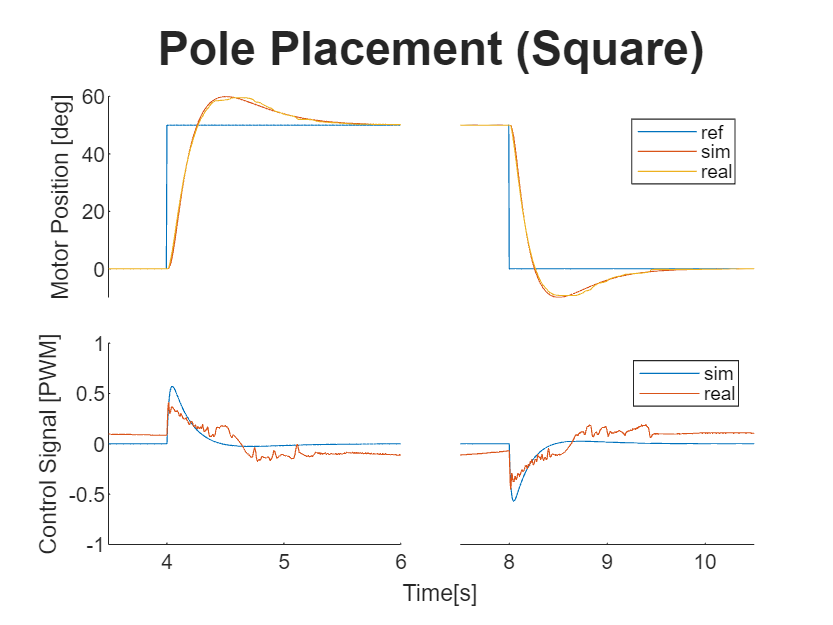

[real_theta_sqr_pp, real_u_sqr_pp] = data_loader.square_signal_loader('result/pp_square.csv',200,8,0,50,1000);
figure;
tiles=tiledlayout(2,2);
tiles.TileSpacing = 'tight';
t = title(tiles,'Pole Placement (Square)');
t.FontName='Times New Roman';
t.FontSize=20;
t.FontWeight='bold';

plt1=nexttile;
hold on;
plot(plt1,time, out.pp_sqr_ref);
plot(plt1,time, out.pp_sqr_theta);
plot(plt1,time, real_theta_sqr_pp);
axis(plt1,[3.5 6 -10 60]);
plt1.XAxis.Visible = 'off';
ylabel(plt1,'Motor Position [deg]');

plt2=nexttile;
hold on;
plot(plt2,time, out.pp_sqr_ref);
plot(plt2,time, out.pp_sqr_theta);
plot(plt2,time, real_theta_sqr_pp);
plt2.XAxis.Visible = 'off';
axis(plt2,[7.5 10.5 -10 60]);
legend(plt2,'ref','sim','real');
legend("Position", [0.75818,0.70569,0.125,0.10476])
plt2.YAxis.Visible = 'off';

plt3=nexttile;
hold on;
plot(plt3,time, out.pp_sqr_u);
plot(plt3,time, real_u_sqr_pp);
axis(plt3,[3.5 6 -1 1]);
ylabel(plt3,'Control Signal [PWM]');
xlabel(plt3,'                       Time[s]','HorizontalAlignment','left');

plt4=nexttile;
hold on;
plot(plt4,time, out.pp_sqr_u);
plot(plt4,time, real_u_sqr_pp);
axis(plt4,[7.5 10.5 -1 1]);
legend(plt4,'sim','real');
legend("Position", [0.76095,0.35085,0.125,0.072619]);
plt4.YAxis.Visible = 'off';

#### Triangle Signal

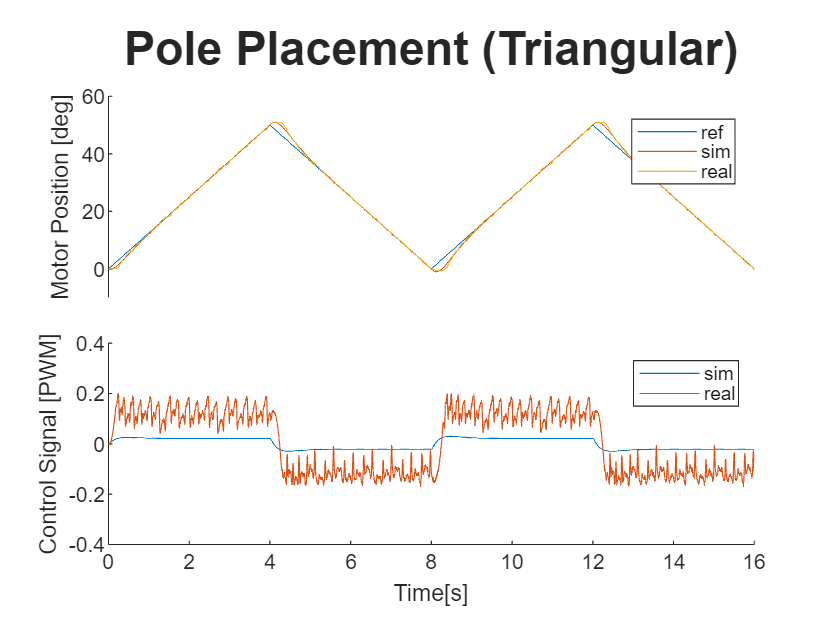

[real_theta_tri_pp, real_u_tri_pp] = data_loader.triangular_signal_loader('result/pp_tri.csv',200,8,0,50,0);
figure;
tiles=tiledlayout(2,1);
tiles.TileSpacing = 'tight';
t = title(tiles,'Pole Placement (Triangular)');
t.FontName='Times New Roman';
t.FontSize=20;
t.FontWeight='bold';

plt1=nexttile;
plt1.XAxis.Visible = 'off';
ylabel(plt1,'Motor Position [deg]');
hold on;
plot(plt1,time, out.pp_tri_ref);
plot(plt1,time, out.pp_tri_theta);
plot(plt1,time, real_theta_tri_pp);
axis(plt1,[0 16 -10 60]);
legend(plt1,'ref','sim','real');
legend("Position", [0.75818,0.70569,0.125,0.10476])

plt2=nexttile;
ylabel(plt2,'Control Signal [PWM]');
hold on;
plot(plt2,time, out.pp_tri_u);
plot(plt2,time, real_u_tri_pp);
axis(plt2,[0 16 -0.4 0.4]);
xlabel(plt2,'Time[s]')
legend(plt2,'sim','real');
legend("Position", [0.76095,0.35085,0.125,0.072619]);

## LQR

#### Square Signal

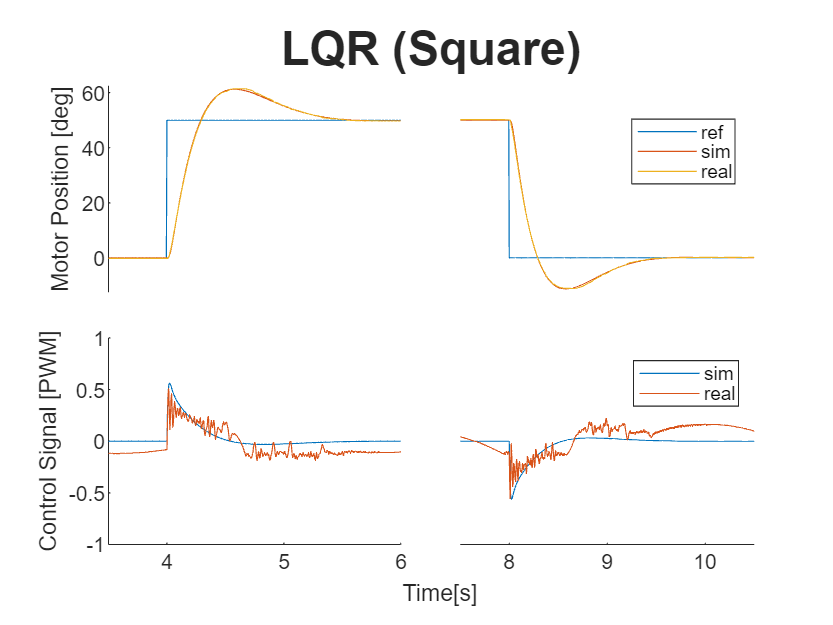

[real_theta_sqr_lqr, real_u_sqr_lqr] = data_loader.square_signal_loader('result/lqr_square.csv',200,8,0,50,1000);
figure;
tiles=tiledlayout(2,2);
tiles.TileSpacing = 'tight';
t = title(tiles,'LQR (Square)');
t.FontName='Times New Roman';
t.FontSize=20;
t.FontWeight='bold';

plt1=nexttile;
hold on;
plot(plt1,time, out.lqr_sqr_ref);
plot(plt1,time, out.lqr_sqr_theta);
plot(plt1,time, real_theta_sqr_lqr);
axis(plt1,[3.5 6 -12.5 62.5]);
plt1.XAxis.Visible = 'off';
ylabel(plt1,'Motor Position [deg]');

plt2=nexttile;
hold on;
plot(plt2,time, out.lqr_sqr_ref);
plot(plt2,time, out.lqr_sqr_theta);
plot(plt2,time, real_theta_sqr_lqr);
plt2.XAxis.Visible = 'off';
axis(plt2,[7.5 10.5 -12.5 62.5]);
legend(plt2,'ref','sim','real');
legend("Position", [0.75818,0.70569,0.125,0.10476])
plt2.YAxis.Visible = 'off';

plt3=nexttile;
hold on;
plot(plt3,time, out.lqr_sqr_u);
plot(plt3,time, real_u_sqr_lqr);
axis(plt3,[3.5 6 -1 1]);
ylabel(plt3,'Control Signal [PWM]');
xlabel(plt3,'                       Time[s]','HorizontalAlignment','left');

plt4=nexttile;
hold on;
plot(plt4,time, out.lqr_sqr_u);
plot(plt4,time, real_u_sqr_lqr);
axis(plt4,[7.5 10.5 -1 1]);
legend(plt4,'sim','real');
legend("Position", [0.76095,0.35085,0.125,0.072619]);
plt4.YAxis.Visible = 'off';

#### Triangle Signal

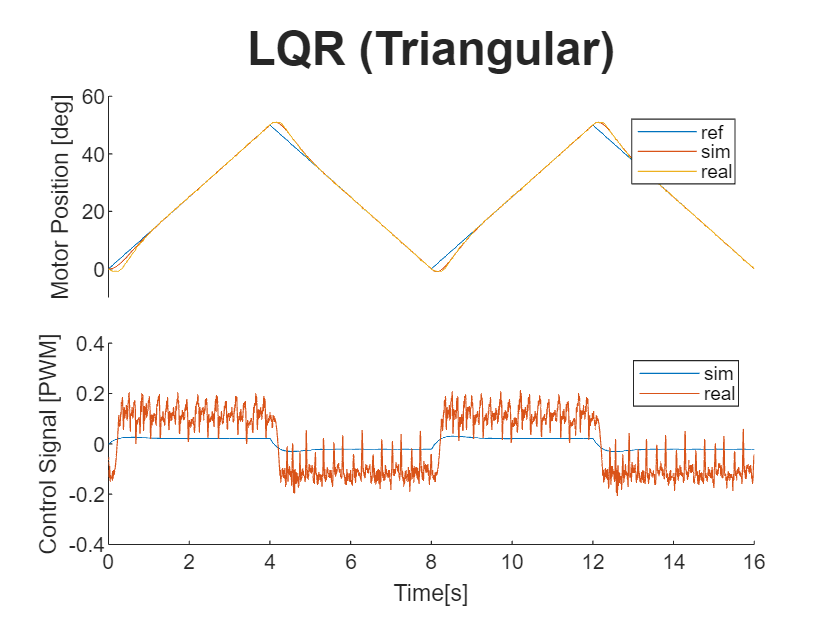

[real_theta_tri_lqr, real_u_tri_lqr] = data_loader.triangular_signal_loader('result/lqr_tri.csv',200,8,0,50,0);
figure;
tiles=tiledlayout(2,1);
tiles.TileSpacing = 'tight';
t = title(tiles,'LQR (Triangular)');
t.FontName='Times New Roman';
t.FontSize=20;
t.FontWeight='bold';

plt1=nexttile;
plt1.XAxis.Visible = 'off';
ylabel(plt1,'Motor Position [deg]');
hold on;
plot(plt1,time, out.lqr_tri_ref);
plot(plt1,time, out.lqr_tri_theta);
plot(plt1,time, real_theta_tri_lqr);
axis(plt1,[0 16 -10 60]);
legend(plt1,'ref','sim','real');
legend("Position", [0.75818,0.70569,0.125,0.10476])

plt2=nexttile;
ylabel(plt2,'Control Signal [PWM]');
hold on;
plot(plt2,time, out.lqr_tri_u);
plot(plt2,time, real_u_tri_lqr);
axis(plt2,[0 16 -0.4 0.4]);
xlabel(plt2,'Time[s]')
legend(plt2,'sim','real');
legend("Position", [0.76095,0.35085,0.125,0.072619]);